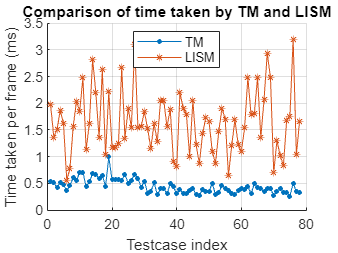

table = readtable('TM_results - Correct Results.csv');
%table_mism = readtable('TM_results_mismatches.csv');

array = table2array(table);
%array_mism = table2array(table_mism);

x = array(:,1);

nms_lism = array(:,3)/100;
nms_tm = array(:,2)/100;

tm_time_ms = array(:,4)/100;
lism_time_ms = array(:,5)/100;

cnms_tm = array(:,6);
cnms_lism = array(:,7);


figure
hold on
grid on
title('Comparison of time taken by TM and LISM')
xlabel('Testcase index')
ylabel('Time taken per frame (ms)')
plot(x, tm_time_ms, 'DisplayName','Tracking Mode', 'Marker', '.', 'MarkerSize', 10)
plot(x, lism_time_ms, 'DisplayName','LIS Mode', 'Marker', '*', 'MarkerSize', 5)

legend('TM','LISM', 'Location', 'North')
hold off

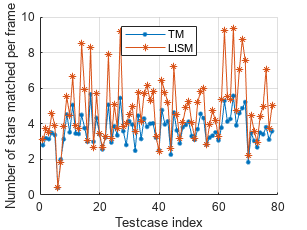



%Number of stars matched plot
figure
hold on
grid on
% title()
xlabel('Testcase index')
ylabel('Number of stars matched per frame')
plot(x, nms_tm, 'Marker', '.', 'MarkerSize', 10)
plot(x, nms_lism, 'Marker', '*', 'MarkerSize', 5)

legend('TM','LISM', 'Location', 'North')
hold off

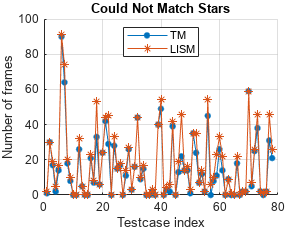



%COULD NOT MATCH STARS PLOT
figure
hold on
grid on
 title('Could Not Match Stars')
xlabel('Testcase index')
ylabel('Number of frames')
plot(x, cnms_tm, 'Marker', '.', 'MarkerSize', 15)
plot(x, cnms_lism, 'Marker', '*', 'MarkerSize', 6)

legend('TM','LISM', 'Location', 'North')
hold off

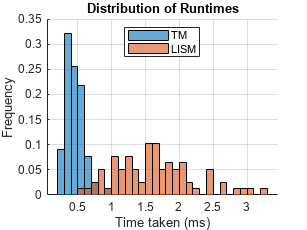


 tm_time_mean = mean(tm_time_ms);
lism_time_mean = mean(lism_time_ms);
tm_time_std = std(tm_time_ms);
lism_time_std = std(lism_time_ms);
coef_of_var_tm = tm_time_std/tm_time_mean;
coef_of_var_lism = lism_time_std/lism_time_mean;


figure 
hold on 
grid on
xlabel('Time taken (ms)')
ylabel('Frequency')
title("Distribution of Runtimes")
histogram(tm_time_ms, 1,'BinWidth',0.1, 'Normalization','probability')
histogram(lism_time_ms,1,'BinWidth',0.1, 'Normalization','probability')
% xline(tm_time_mean, 'Color', 'blue')
% xline(lism_time_mean, 'Color', '#D95319')
% xticks([0 178.32 500 575.18 1000 1500])
% xticklabels({'0', 't_{TM}', '500', 't_{LISM}', '1000', '1500'})
legend('TM','LISM', 'Location', 'North')
hold off

% 
% figure
% hold on 
% grid on
% xlabel('Testcase Index')
% ylabel('Matching Accuracy (in %)')
% % yline(100)
% ylim([50 100])
% plot(array_mism(:,1), array_mism(:,7), 'Marker', '.', 'MarkerSize', 20)
% % histogram(array_mism(:,7))
% % yline(mean(array_mism(:,7)))
% hold off
